Simulate an LFP time series and then analyze it using our broadband extraction method. 

SIMULATION: 

We simulate the LFP time series in 3 steps: 

- There is an underlying, noiseless time series, which can be thought of as the idealized rate of spike arrivals per neuron. 

- We generate noisy samples scaled to this rate, which can be thought of as a poisson-like nonlinearity defining the spike arrivals. 

- We temporally integrate the noisy time series, which can be thought of as the dendritic integration of the currents arising from spike arrivals.

ANALYSIS: 

After generating multiple noisy time series with the identical underlying time-varying rate, we analyze the time series by:

- Extracting the broadband envelope in each trial using one of several algorithms and averaging the envelopes across trials.

- Comparing the estimated time-varying broadband envelopes to the noiseless time-varying rate used to seed the time series.

## SIMULATION

Set parameters for the simulation. For example, choose the response profile of the LFP time series and leaky temporal integration, and add additive noise.

params = [];

% Set parameters for the noiseless, time-varying rate 
params.simulation.resp        = 'boxcar';                % response profile: choose from {'boxcar' 'steps' 'step' 'pulse' 'bump' 'square' 'sine' 'noise' 'pred dn' 'level'} ([default = step];
params.simulation.t           = (-1999.5:1999.5)';       % trial length: trials are -2 to 2 seconds, and later clipped to [0 1] to avoid edge artifacts
params.simulation.srate       = 1000;                    % sample rate (Hz) 
params.simulation.opt.f       = 0;                       % temporal frequency of response profile, applicable to 'sine' or 'square' wave profiles
params.simulation.opt.level   = 3;                       % average level of response, applicable to 'level' response profile

% Set parameters for noisy samples
params.simulation.nn          = 100;                     % number of neurons
params.simulation.ntrials     = 12;                      % number of repeated trials
params.simulation.seed        = 0;                       % use same number to compare simulations for same random generator of samples; leave empty to use new generator every time

% Set parameters for leaky integration
params.simulation.alpha       = 0.1;                     % time constant for dendritic leakage
params.simulation.tau         = 0.0023;                  % time constant for post-synaptic current

% Set parameters for noise
params.simulation.addnoise   = 0;%0.01;                  % additive noise (if 0, no noise is added)

% Set parameters for plotting
params.plot.on     = 'yes';                              % yes/no
params.plot.fontsz = 18;                                 % font size
params.plot.lnwdth = 3;                                  % line width    


## Step 1: Simulate noiseless timeseries

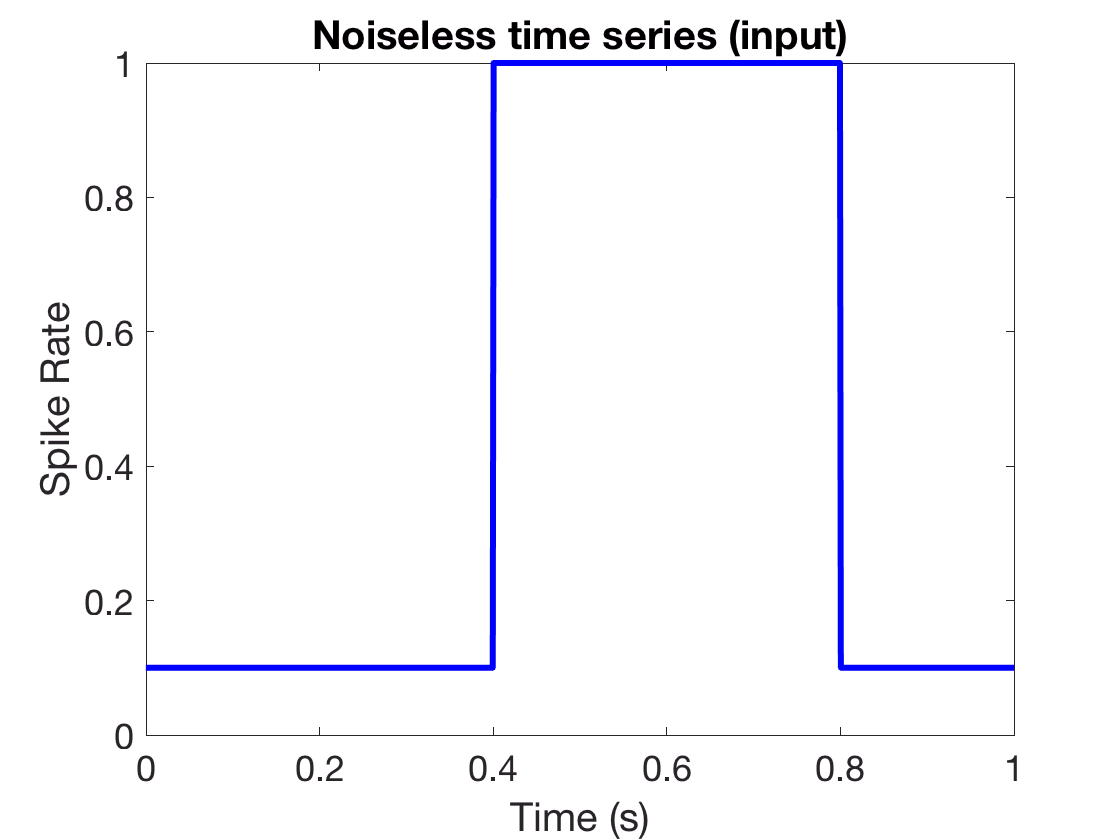

[spikeRate, params] = generateNoiselessTimeCourse(params);

## Step 2: Generate multiple noisy samples of time series

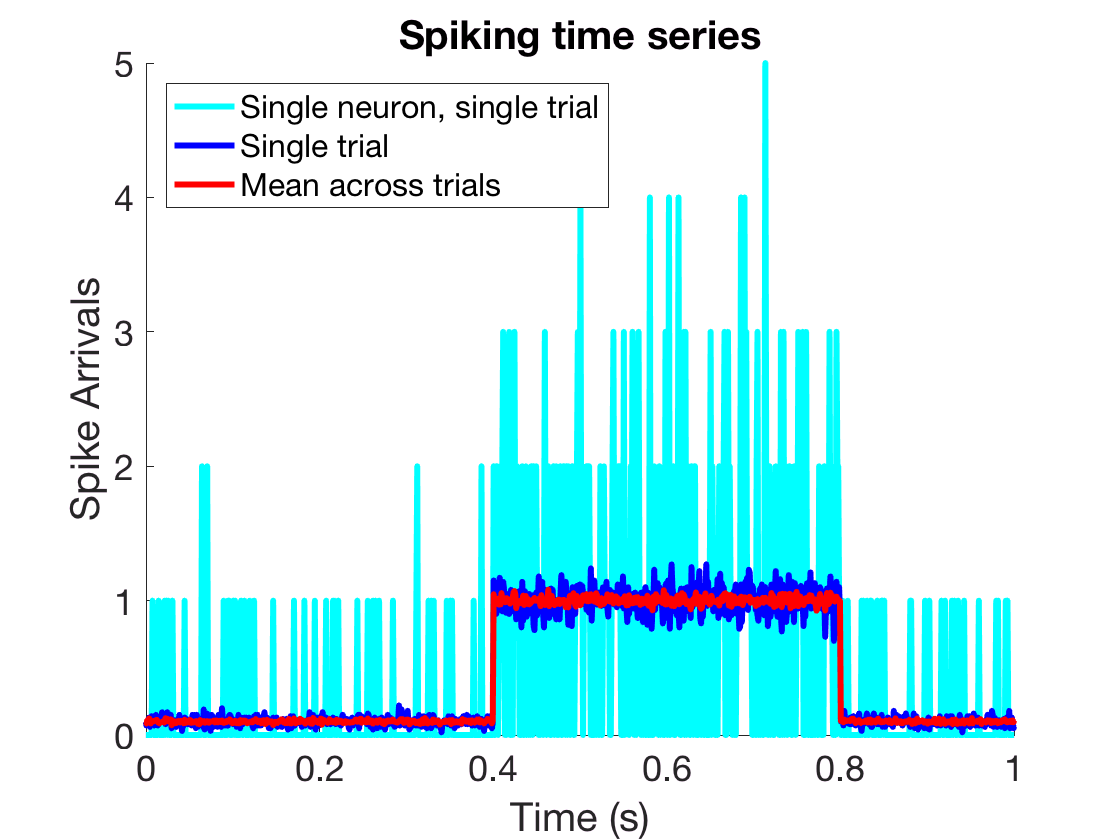

[spikeArrivals, params] = generateNoisySampledTimeCourses(spikeRate, params);

## Step 3: Temporally integrate dendritic currents

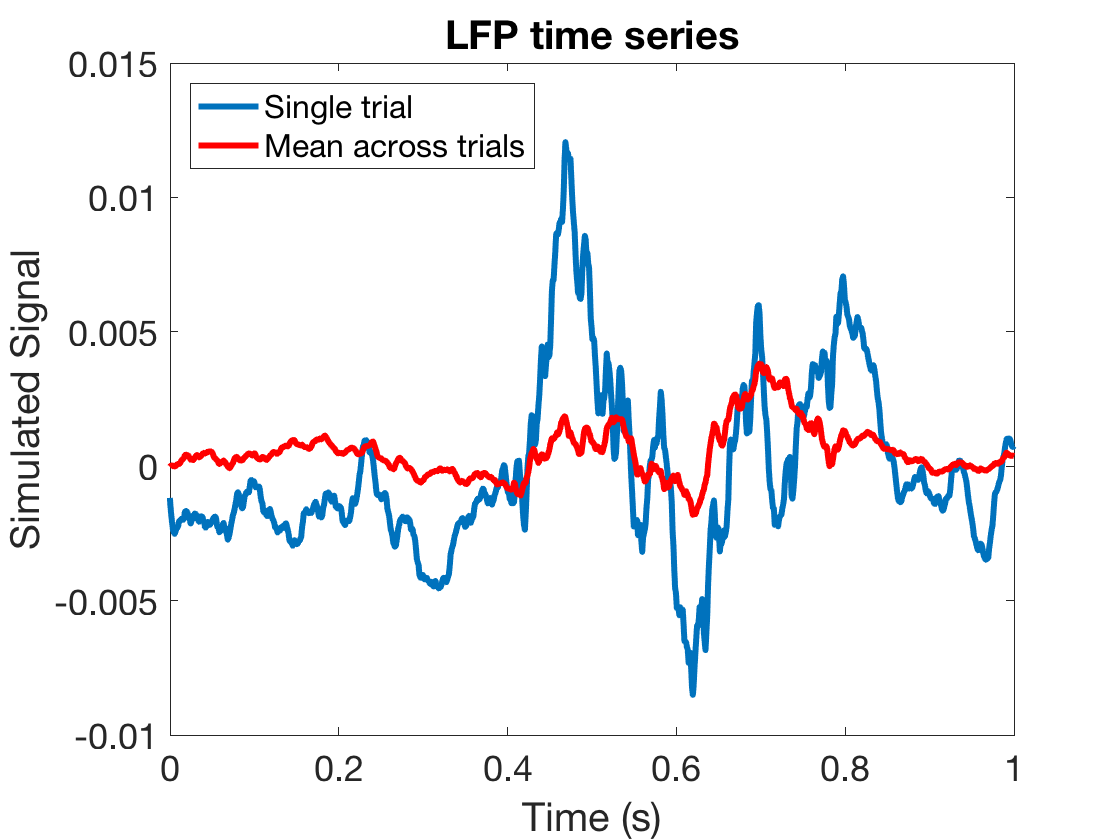

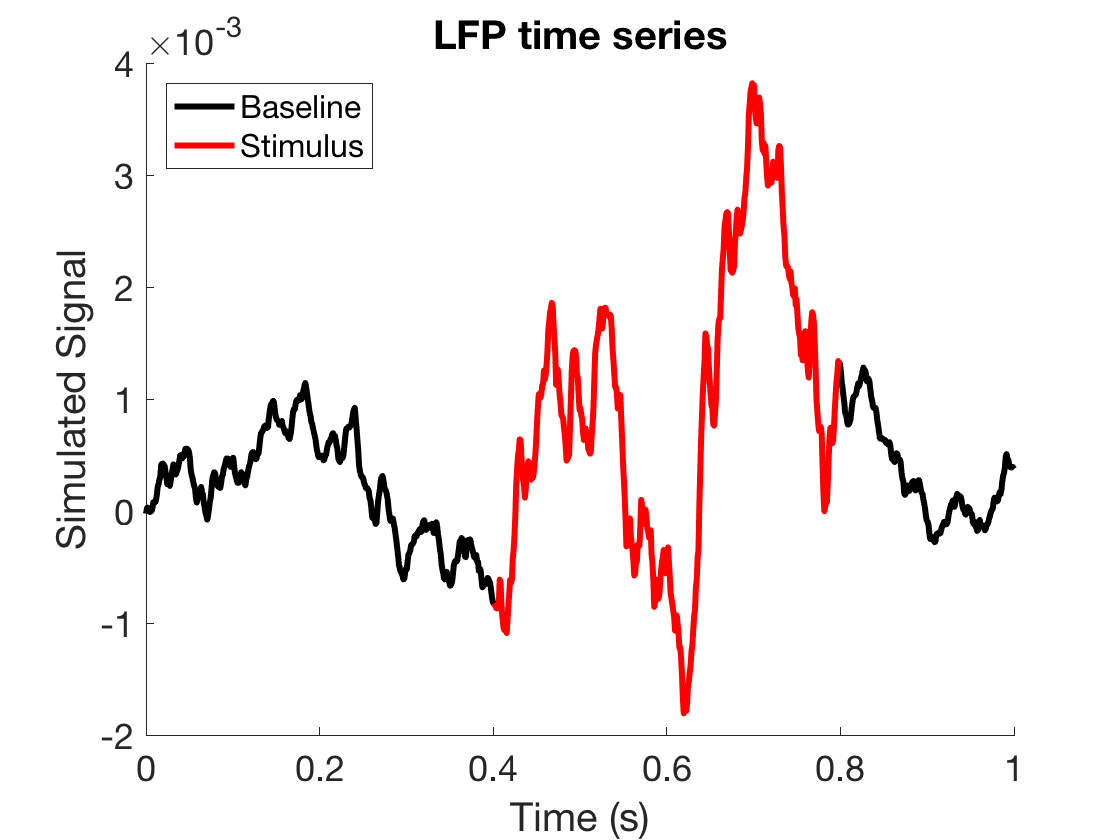

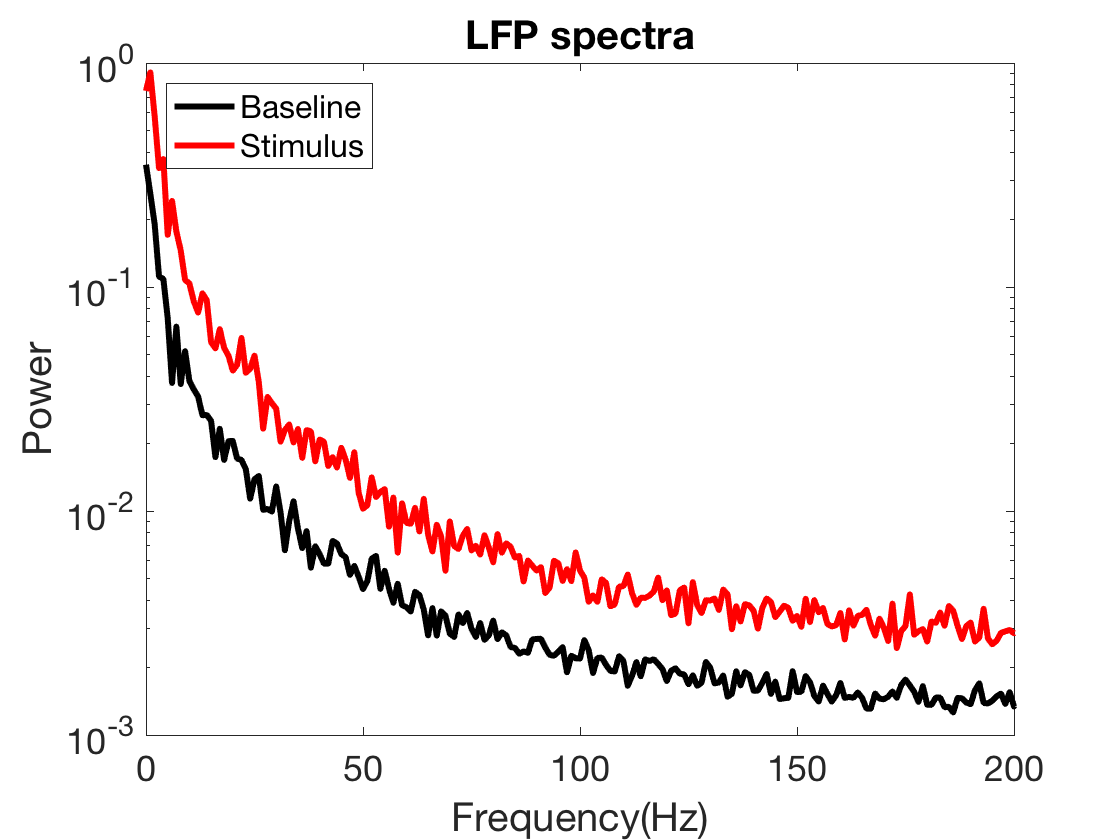

[simulatedSignal] = generateIntegratedTimeSeries(spikeArrivals, params);

## ANALYSIS

Set parameters for the analysis. For example, choose the bandwidth, whether to perform whitening across bands, and which measure to compute (e.g. power or amplitude):


% Define frequency bands and method for extracting broadband
params.analysis.bands            = {[40 200], 20};         % {[lower bound,  upper bound], window sz}
params.analysis.averagebandshow  = 'geomean';             % geomean/mean
params.analysis.averagebandswhen = 'after hilbert';       % 'before hilbert'/'after hilbert'
params.analysis.whitenbands      = 'no';                  % yes/no
params.analysis.measure          = 'amplitude';           % amplitude/power/logpower

## Step 4: Compute broadband

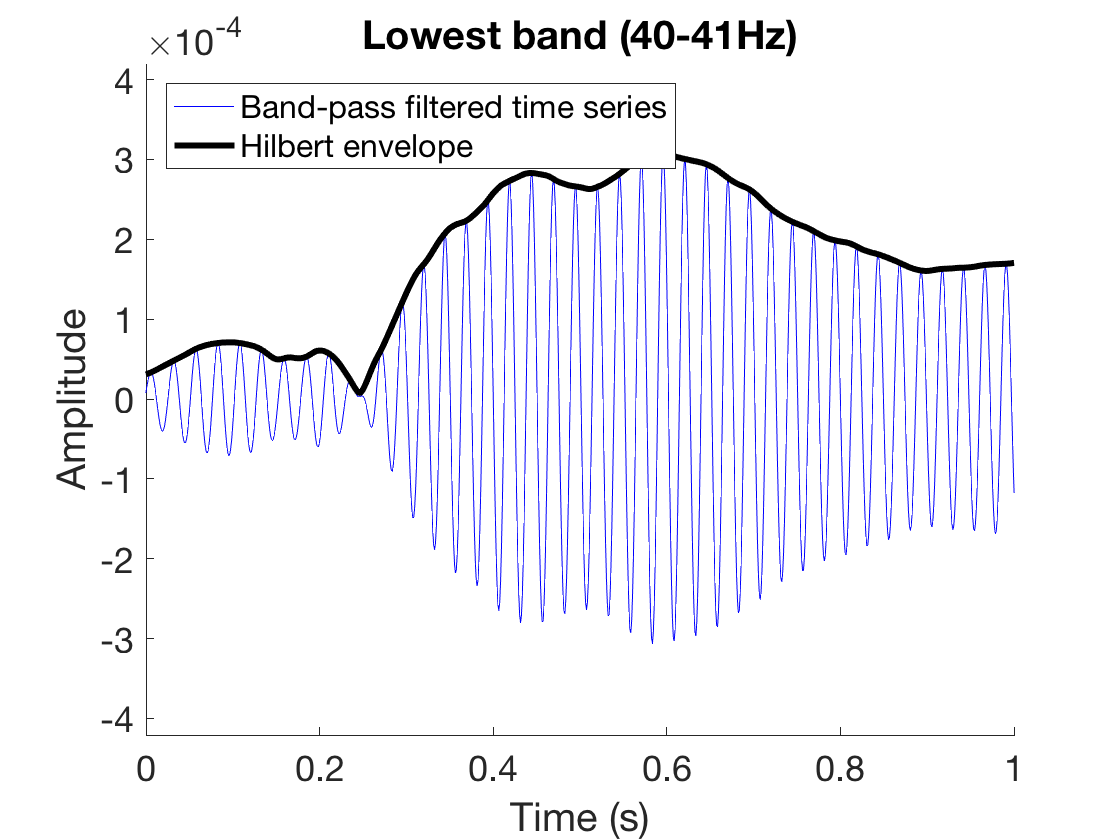

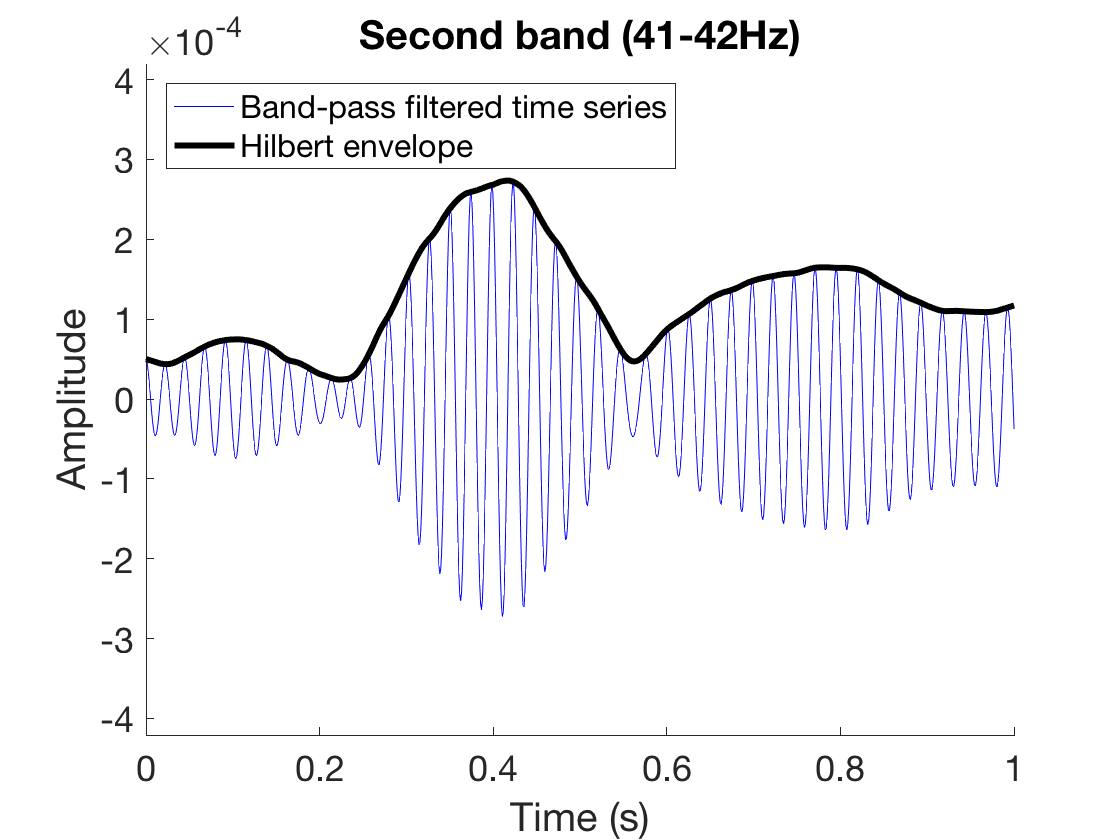

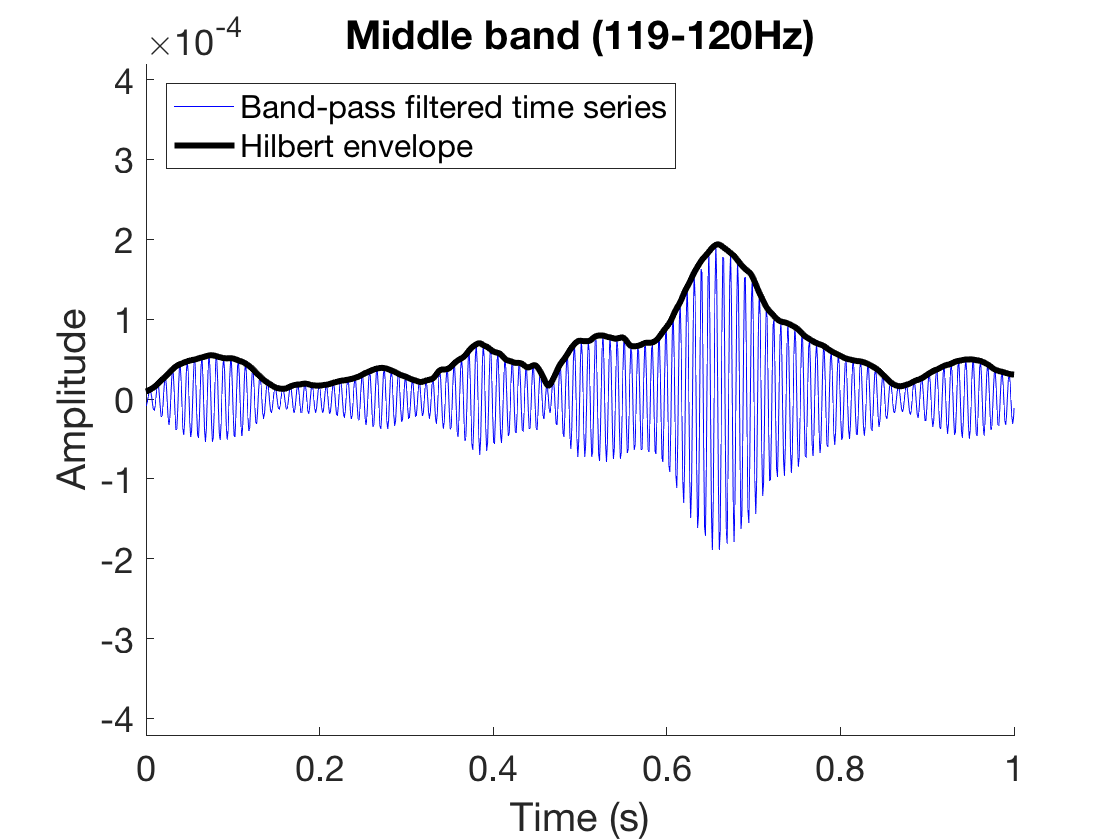

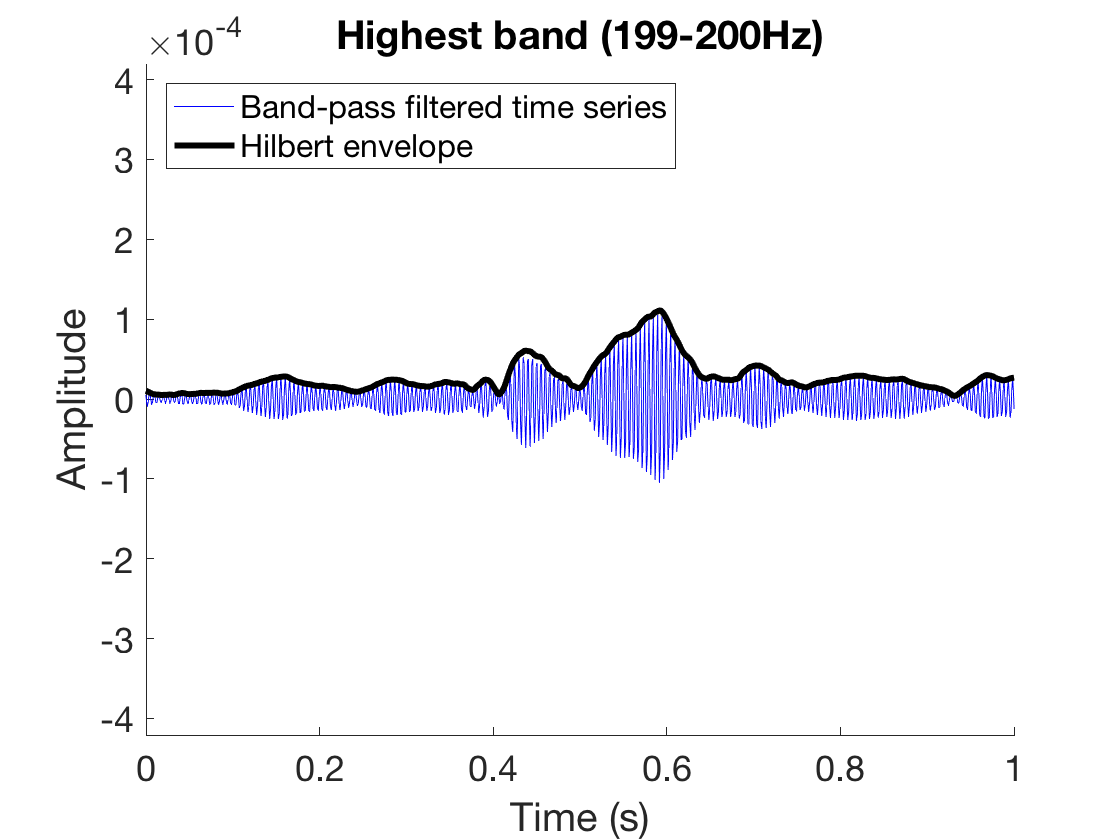

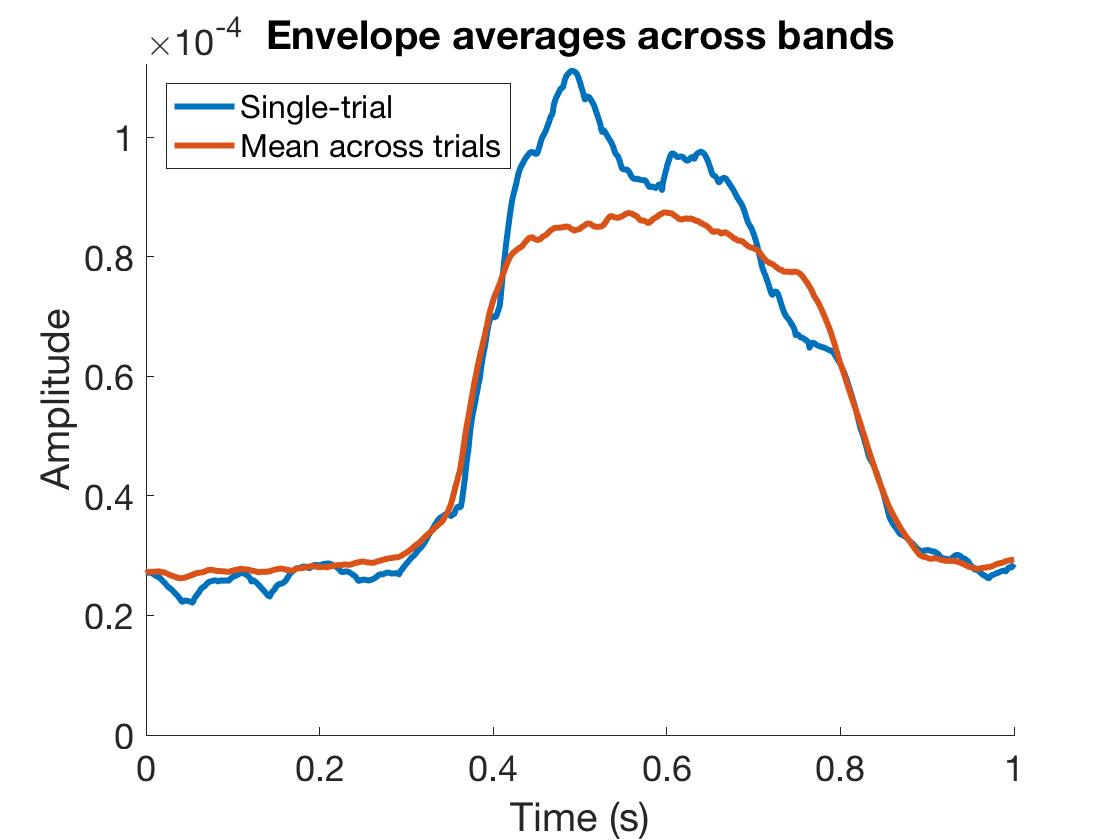

[estimatedBroadband, params] = extractBroadband(simulatedSignal, params);

## Step 5: Compare with the input signal

Here we plot the simulated time series and the broadband time series and compare them via regression. 

This comparison involves a calibration step to relate the output units of the broadband calculation to the input units of the simulated spike rates. It consists of a **separate **simulation of 100 trials with broadband responses to spike rates of level 0 and 1 (plus spontaneous rate), computed with the same broadband analysis parameters as the main analysis. We then extract a linear slope and intercept parameter which are used to scale the responses to the main analysis, which can consist of a more complex input pattern (e.g. bigsteps, smallsteps, or sine). This means that the broadband computation should be fairly accurate for response levels of 0 and 1 in the response profile that is tested in the main analysis. It doesn't predict though how responses will scale for intermediate levels (e.g. smallsteps), levels outside the calibrated range (e.g. bigsteps), or the temporal precision with which the onset of the 1-level activity is reflected in the broadband time series. 

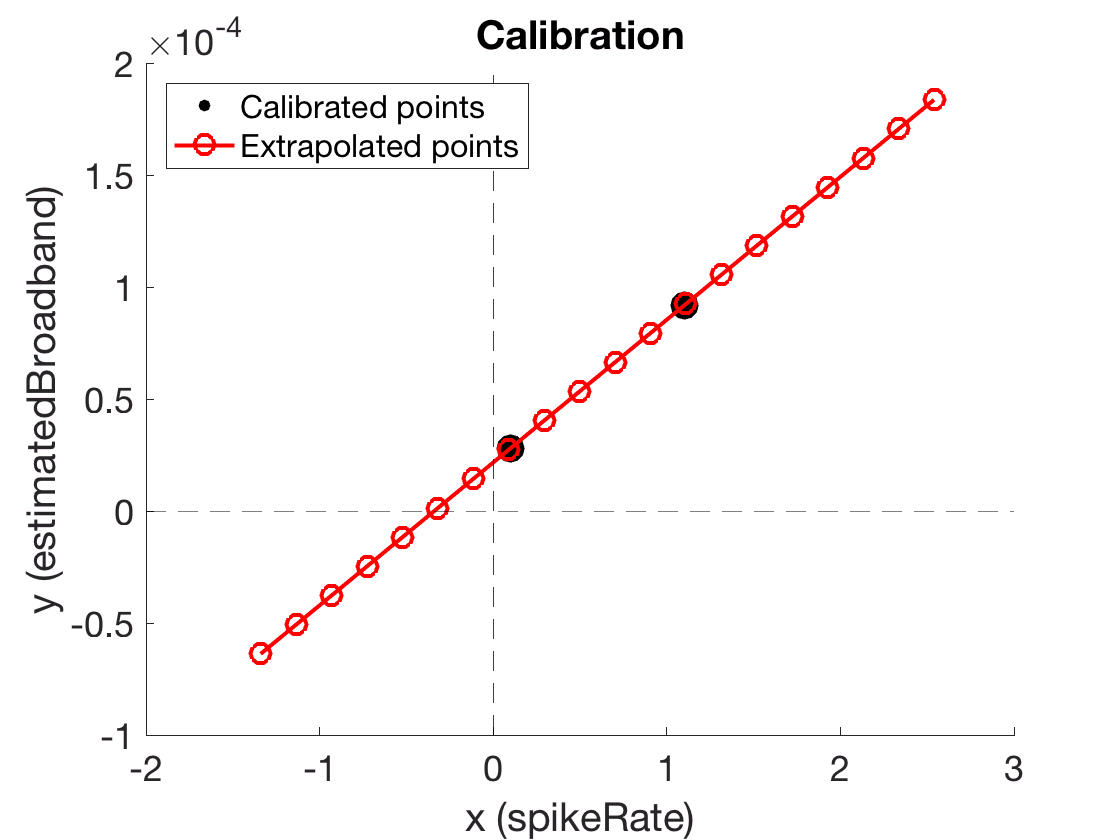

[results, params] = evaluateBroadband(spikeRate, estimatedBroadband, params); 

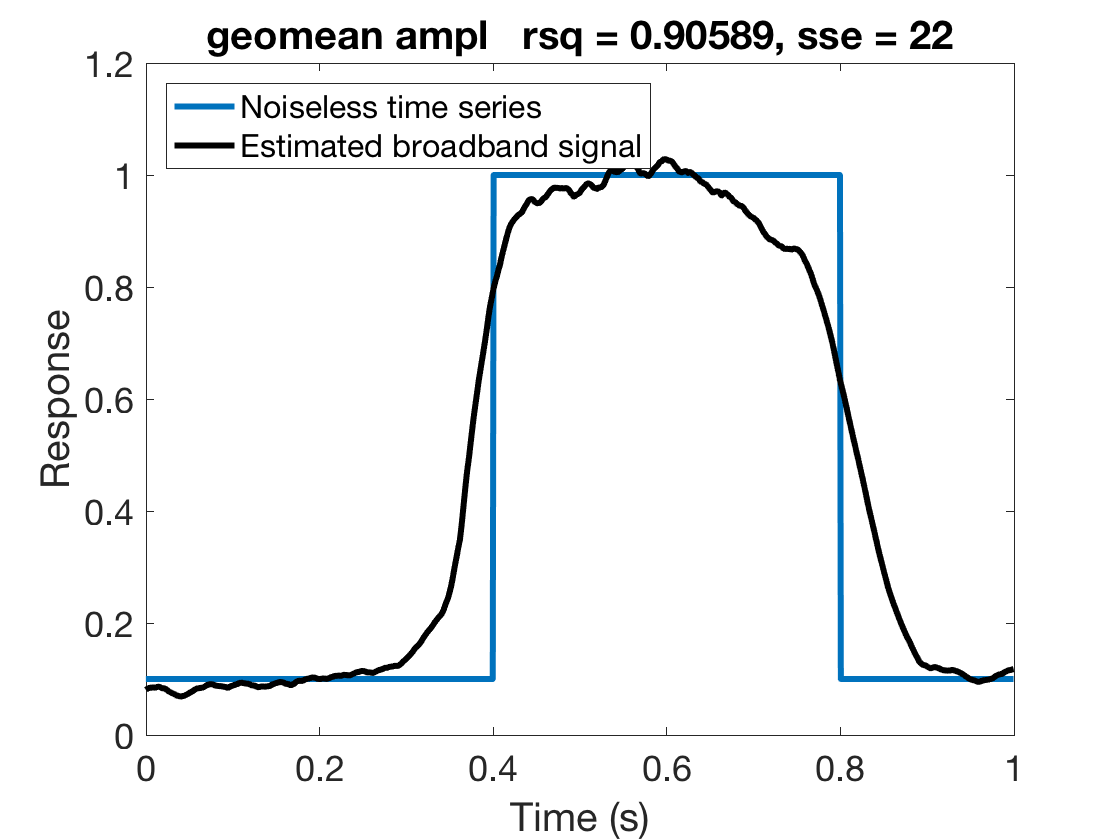

ti = get(gca, 'Title');
title([ti.String ' rsq = ' num2str(results.regress.rsq) ', sse = ' num2str(round(results.regress.sse))]);

## SYSTEMATIC COMPARISONS OF SIMULATIONS / ANALYSES 

## Question 1: Amplitude vs. power vs log power

How does the quality of broadband estimate vary using amplitude, power or log power estimates?

Prediction: Power best quality because of Poisson generator

Approach: vary params.method

For systematic comparisons in simulations, see:

% q1_comparisonOfBroadbandMeasures_timecourses.m
% q1_comparisonOfBroadbandMeasures_levels.m

For demonstration of effects in real data, see:

% d1_comparisonsOfBroadbandMeasuresInRealData.m	

## Question 2: Temporal precision

How is temporal precision of broadband estimate affected by analysis parameters? 

Prediction: Time series containing sharp transients (i.e. high temp freq) need wide bands (more time precision)

Approach: vary params.resp and params.bands, where is the optimum?

For systematic comparisons in simulations, see:

% q2_temporalPrecisionOfBroadbandAnalysis_timecourses.m
% q2_temporalPrecisionOfBroadbandAnalysis_byfrequency.m
% q2_temporalPrecisionOfBroadbandAnalysis_levels.m

 For demonstration of effects in real data, see:

% d2_comparisonsOfBandwidthsInRealData.m

## Question 3: Additive noise

How is the quality of the broadband estimate affected by additive noise

Prediction: Quality decreases for high bands under conditions of high noise

Approach: vary params.addnoise and params.bands, where is the optimum?

For systematic comparisons in simulations, see:

% q3_effectsOfAdditiveNoise.m

## Comments

Impression from playing around with parameters for broadband analysis: 

* Averaging bands after broadband computation = preferred (less noisy time course)

* Mean power across bands higher R2 compared to amplitude and log power 

* Geomean leads to slightly higher r2 and better captures high frequency information

* Whitening doesn't improve results

Unresolved questions in simulation/analysis:

* What other / better quantification metrics besides regression to use? 

What are the implications for REAL data analysis:

* Given assumptions XY, e.g. amplitude vs power, will affect interpretation of selectivity (e.g. face response 2x or 4x as high as house response), contrast response functions

* How well can we capture actual transients in the data? (depends on how transient we think actual neural responses are); relevant for estimation of onsets, temporal summation & integration

## Poster SfN 2017 feedback

* Implications for gamma / oscillatory components of signal?

* Would be interesting to run similar analyses in animal electrophysiological data, see if consistent, test/validate spiking-to-LFP model

* Noise modeling: how about trial-to-trial variance / influence of outlier trials, those may have more effect on power than logpower (someone's personal experience), a lot of ECoG methods 'heritated from EEG'